Observations

numObs = 3;
obsInfo = rlNumericSpec([numObs 1], 'LowerLimit', [-inf -inf 0]', 'UpperLimit', [inf inf inf]');
obsInfo.Name = 'integrated error, error, and gap';

Actions

numAct = 1;
actInfo = rlNumericSpec([numAct 1]);
actInfo.Name = 'Voltage';

mdl = 'btp_rl_reward2';
open_system(mdl)

%blk = mdl + '/RL Agent';
env = rlSimulinkEnv(mdl, [mdl '/RL Agent'], obsInfo, actInfo);

obsInfo = getObservationInfo(env)

obsInfo =   rlNumericSpec with properties:

     LowerLimit: [3×1 double]
     UpperLimit: [3×1 double]
           Name: "integrated error, error, and gap"
    Description: [0×0 string]
      Dimension: [3 1]
       DataType: "double"


actInfo = getActionInfo(env)

actInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "Voltage"
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"



%env.ResetFcn = @(in)localResetFcn(in); (without randomising initial height)

%validateEnvironment(env)
Ts = 10;     % originally 1.0
Tf = 200;

%reinforcementLearningDesigner

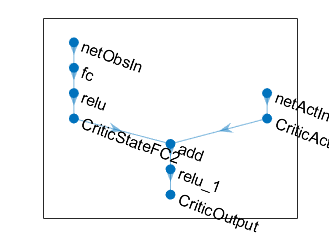

statePath = [
 featureInputLayer(obsInfo.Dimension(1),Name="netObsIn")
 fullyConnectedLayer(50)
 reluLayer
 fullyConnectedLayer(25,Name="CriticStateFC2")];

actionPath = [
 featureInputLayer(actInfo.Dimension(1),Name="netActIn")
 fullyConnectedLayer(25,Name="CriticActionFC1")];

commonPath = [
 additionLayer(2,Name="add")
 reluLayer
 fullyConnectedLayer(1,Name="CriticOutput")];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork, ...
 "CriticStateFC2", ...
 "add/in1");
criticNetwork = connectLayers(criticNetwork, ...
 "CriticActionFC1", ...
 "add/in2");

figure
plot(criticNetwork)


criticNetwork = dlnetwork(criticNetwork);
%summary(criticNetwork)

critic = rlQValueFunction(criticNetwork,obsInfo,actInfo, ...
 ObservationInputNames="netObsIn", ...
 ActionInputNames="netActIn");

getValue(critic, ...
 {rand(obsInfo.Dimension)}, ...
 {rand(actInfo.Dimension)})

ans = single
0.1644

actorNetwork = [
 featureInputLayer(obsInfo.Dimension(1))
 fullyConnectedLayer(3)
 tanhLayer
 fullyConnectedLayer(actInfo.Dimension(1))
 ];

actorNetwork = dlnetwork(actorNetwork);
%summary(actorNetwork)

actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

getAction(actor,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[-0.5486]}


agent = rlDDPGAgent(actor,critic);

agent.SampleTime = Ts;

agent.AgentOptions.TargetSmoothFactor = 1e-3;
agent.AgentOptions.DiscountFactor = 1.0;
agent.AgentOptions.MiniBatchSize = 64;
agent.AgentOptions.ExperienceBufferLength = 1e6;

agent.AgentOptions.NoiseOptions.Variance = 0.3;
agent.AgentOptions.NoiseOptions.VarianceDecayRate = 1e-5;

agent.AgentOptions.CriticOptimizerOptions.LearnRate = 1e-03;
agent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;
agent.AgentOptions.ActorOptimizerOptions.LearnRate = 1e-04;
agent.AgentOptions.ActorOptimizerOptions.GradientThreshold = 1;

getAction(agent,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[-0.5333]}


trainOpts = rlTrainingOptions(...
 MaxEpisodes=100, ...
 MaxStepsPerEpisode=ceil(Tf/Ts), ...
 ScoreAveragingWindowLength=20, ...
 Verbose=false, ...
 Plots="training-progress",...
 StopTrainingCriteria="AverageReward",...
 StopTrainingValue=800);

%validateEnvironment(env)

trainingStats = train(agent,env,trainOpts);

simOpts = rlSimulationOptions(MaxSteps=ceil(Tf/Ts),StopOnError="on");
experiences = sim(env,agent,simOpts);

Dot indexing is not supported for variables of this type.

Error in rl.util.expstruct2timeserstruct (line 7)
observation     = {experiences.Observation}; 

Error in rl.env.AbstractEnv/sim (line 129)
            s = rl.util.expstruct2timeserstruct(exp,time,oinfo,ainfo);